clear
clc
%%%%%% Assumption
% T_upper = T_lower = W/2

%%%%%% COMMON VALUES
%%% Environment
rho_0 = 1.225;    % kg/m^3
T_0 = 288.2;      % K
P_0 = 101325;     % pa
gamma = 1.4;
R_0 = 287.05;
g = 9.8067;       % m/s^2
T_trans = 272.15; % K to °C
%%% Aero team
MTOW = 3491;   % kg     % max take off weight
Wpay = 800;    % kg     % Weight of the payload
Nb = 3;
R = 5.2992;    % m
c = 0.265;     % m      % chord length
Cd0 = 0.01;
omega = 41.5153;        % rotational speed
f = 3.4177;             % equivalent wetted area
t_c = 0.08;                % thickness ratio
M_dd = 0.86;            % drag divergence Mach number
sweep = 30;    % degree % sweep angle
kappa_ii = 1.1412;       % induce factor
kappa_02 = 4;           % profile factor (mu^2 term)
kappa_04 = 5/8;         % profile factor (mu^4 term)
kappa_int = 1.16;       % interference factor
%%% struc team

%%% syst team
Ne = 2;      % number of engines
Paux_total = 1;    % power needed (the on board equipments)
SFC = 8.57*10^-8;     % kg/(W*s)
Wf = 508;      % initial fuel weight
Ptotal = 1.5*10^6;  % total power provided by engines
kappa_trans = 1; % transmission factor
%%% Initial calc
GTOW = (MTOW - Wpay) * g;   % N    % gross take off weight(no payload)
MTOW = MTOW * g;            % N
Wpay = Wpay * g;            % N
Wf = Wf * g;                % N
A = pi * R^2;               % m^2  % rotor area
sigema = Nb * c / (pi * R);        % solidity
T_0 = T_0 - T_trans;        % °C

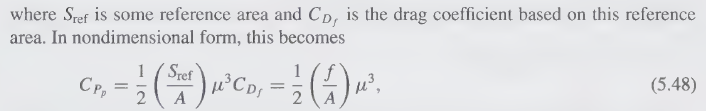

%%%%%% h in feet, T in °C, others in SI units
%%%%%% G indicates no payload, M indicates max payload, V_forward indicates
%%%%%% forward flight speed of aircraft in m/s

%%%%%% max ceiling
h = 0;
V_forward = 0:0.1:90;
mu = V_forward ./ (omega * R);
alp = zeros(length(V_forward));

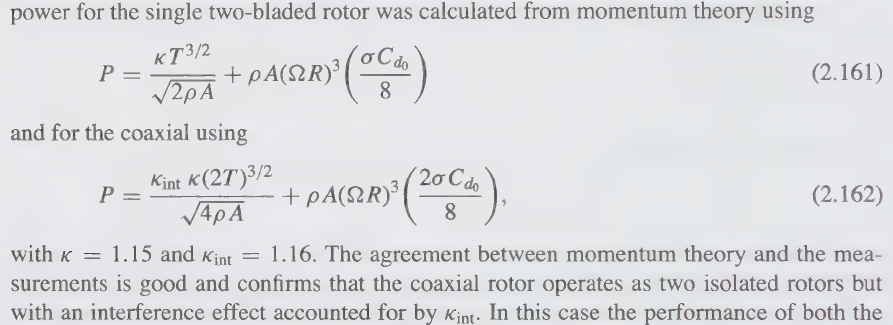

Pi = kappa * T * v

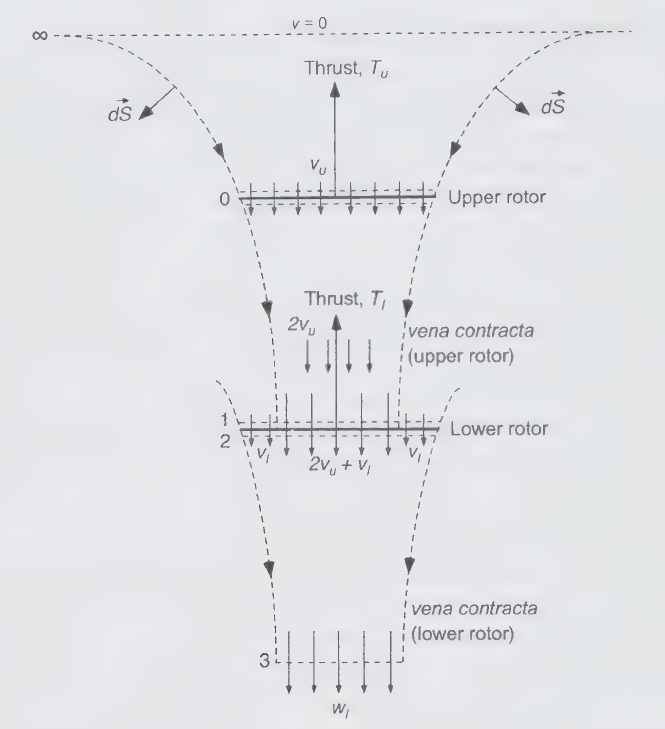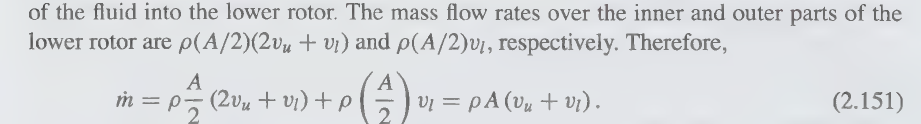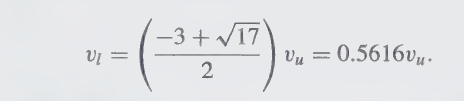

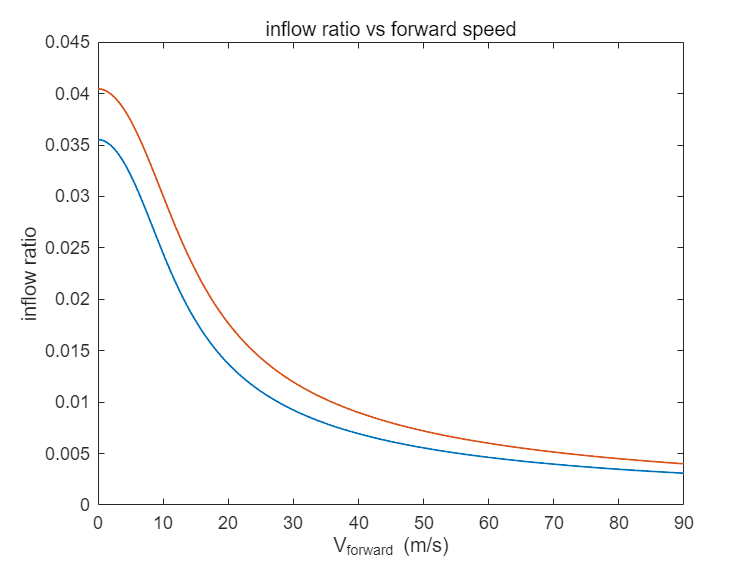

% Pi clac
CT_msl_G = GTOW/(2*rho_0*A*omega^2*R^2);
lambda_msl_initial_G = sqrt(CT_msl_G/2);
lambda_msl_n = lambda_msl_initial_G;
lambda_msl_G = zeros(size(V_forward));
for j = 1:length(V_forward)
    for i = 1:100
        lambda_msl_n1 = mu(j)*tan(alp(j)) + CT_msl_G / (2*sqrt(mu(j)^2 + lambda_msl_n^2));
        lambda_msl_n = lambda_msl_n1;
    end
    lambda_msl_G(j) = lambda_msl_n1;
end

CT_msl_M = MTOW/(2*rho_0*A*omega^2*R^2);
lambda_msl_initial_M = sqrt(CT_msl_M/2);
lambda_msl_n = lambda_msl_initial_M;
lambda_msl_M = zeros(size(V_forward));
for j = 1:length(V_forward)
    for i = 1:100
        lambda_msl_n1 = mu(j)*tan(alp(j)) + CT_msl_M / (2*sqrt(mu(j)^2 + lambda_msl_n^2));
        lambda_msl_n = lambda_msl_n1;
    end
    lambda_msl_M(j) = lambda_msl_n1;
end
figure
plot(V_forward,lambda_msl_G,LineWidth=1)
hold on
plot(V_forward,lambda_msl_M,LineWidth=1)
title('inflow ratio vs forward speed')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('inflow ratio')
hold off

kappa_i = kappa_ii .* cosh(7.5 .* mu.^2);
Pi_msl_G = (kappa_int * GTOW/2 * omega * R * 2) .* lambda_msl_G .* kappa_i;
Pi_msl_M = (kappa_int * MTOW/2 * omega * R * 2) .* lambda_msl_M .* kappa_i;
Cpp_msl = (0.5 * f / A) .* mu.^3;
Pp_msl = Cpp_msl .* (rho_0 * A * omega^3 * R^3);

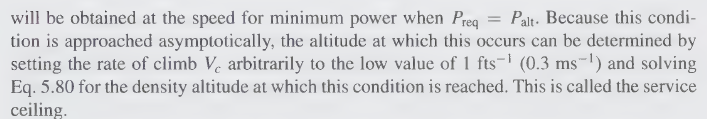

Pc_msl_G = 0.3 * GTOW *ones(size(V_forward));
Pc_msl_M = 0.3 * MTOW *ones(size(V_forward));
Paux_msl = Paux_total *ones(size(V_forward));

% Po calc
Cpo_pure = sigema * Cd0 .* (1 + kappa_02.*mu.^2 + kappa_04.*mu.^4) ./ 8;

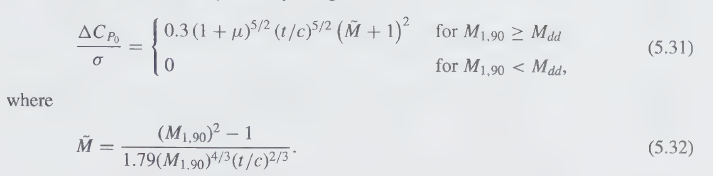

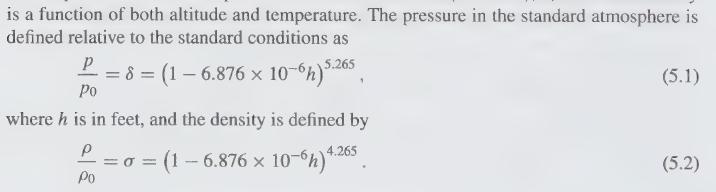

h_M = h;
M_19 = (omega * R + V_forward) ./ sqrt(gamma * R_0 * ((15 - 0.001981 * h_M) + T_trans));
M_hat = (M_19.^2 - 1) ./ (1.79 .* M_19.^(4/3) .* t_c^(2/3));
M_hover = (omega * R) / sqrt(gamma * R_0 * ((15 - 0.001981 * h_M) + T_trans));
delta_Cpo = zeros(size(V_forward));
for i = 1:length(V_forward)
    if M_19(i) >= M_dd
        delta_Cpo1 = sigema * (0.3 * (1+mu(i))^(5/2) * t_c^(5/2) * (M_hat(i)+1)^2);
    else
        delta_Cpo1 = 0;
    end

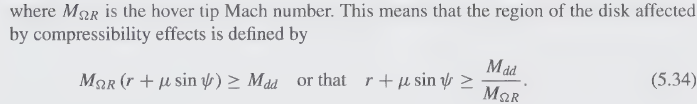

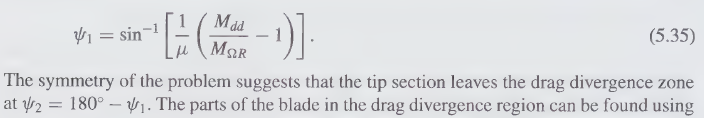

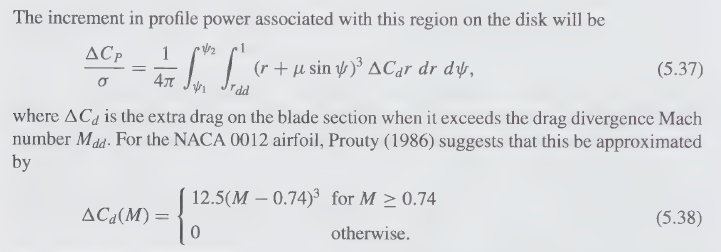

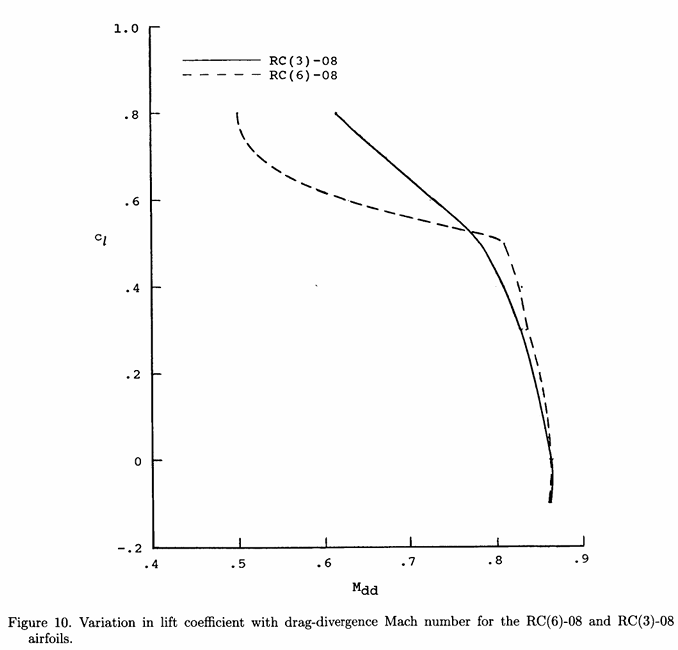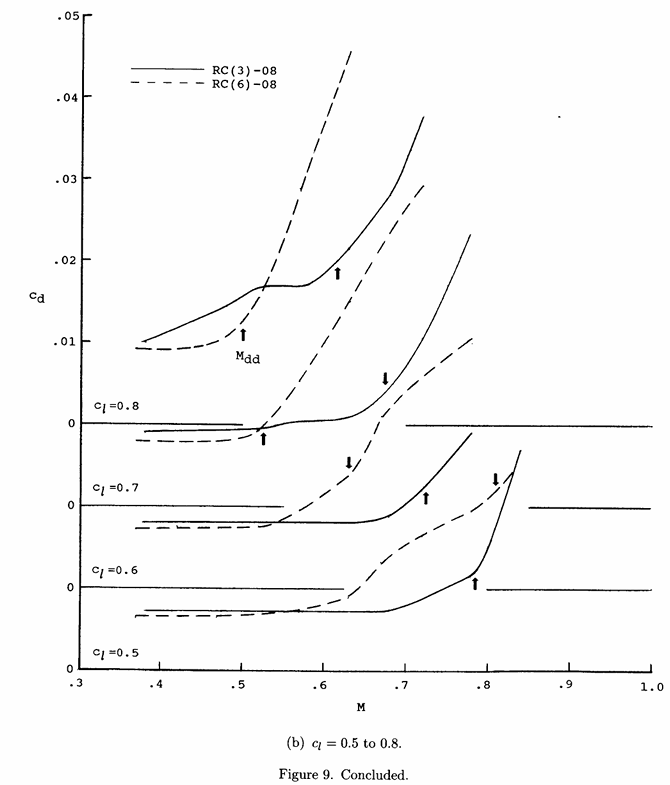

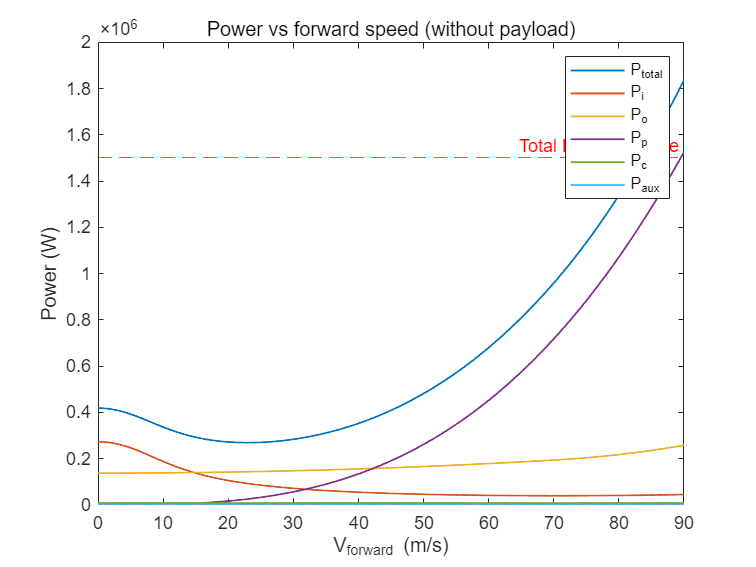

    % Assumption: tip relief only occurs at RC6-08 part (85%---100%)
    M_r = M_hover*(1+mu(i))*cos(sweep);
    if M_r >= M_dd
        psi1 = asin(mu(i)^-1 * (M_dd/M_hover - 1));
        psi2 = 180 - psi1;
        f = @(psi,r) (r + mu(i)*sin(psi))^3 * r * (0.165*M_hover*(r+mu(i)*sin(psi))*cos(sweep)-0.0895)
        delta_Cpo2 = sigema * integral2(f,psi1,psi2,@(psi) M_dd/M_hover - mu(i)*sin(psi),1) / (4 * pi)
    else
        delta_Cpo2 = 0;
    end
    delta_Cpo(i) = delta_Cpo2 + delta_Cpo1;
end
Po_msl = (Cpo_pure+delta_Cpo) .* (2 * A * omega^3 * R^3 * rho_0*(1-6.876*10^-6*h_M)^4.265);
P_msl_G = (Pi_msl_G + Po_msl + Pp_msl + Paux_msl) .* kappa_trans;
P_msl_M = (Pi_msl_M + Po_msl + Pp_msl + Paux_msl) .* kappa_trans;
P_msl_ceiling_G = (Pi_msl_G + Po_msl + Pp_msl + Pc_msl_G + Paux_msl) .* kappa_trans;
P_msl_ceiling_M = (Pi_msl_M + Po_msl + Pp_msl + Pc_msl_M + Paux_msl) .* kappa_trans;
figure
plot(V_forward,P_msl_ceiling_G,LineWidth=1)
hold on
plot(V_forward,Pi_msl_G,LineWidth=1)
hold on
plot(V_forward,Po_msl,LineWidth=1)
hold on
plot(V_forward,Pp_msl,LineWidth=1)
hold on
plot(V_forward,Pc_msl_G,LineWidth=1)
hold on
plot(V_forward,Paux_msl,LineWidth=1)
hold on
yline(Ptotal, '--r', 'Total Power avalible');  % 红色虚线，并加标签
hold on
legend('P_t_o_t_a_l','P_i','P_o','P_p','P_c','P_a_u_x')
title('Power vs forward speed (without payload)')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('Power (W)')
hold off

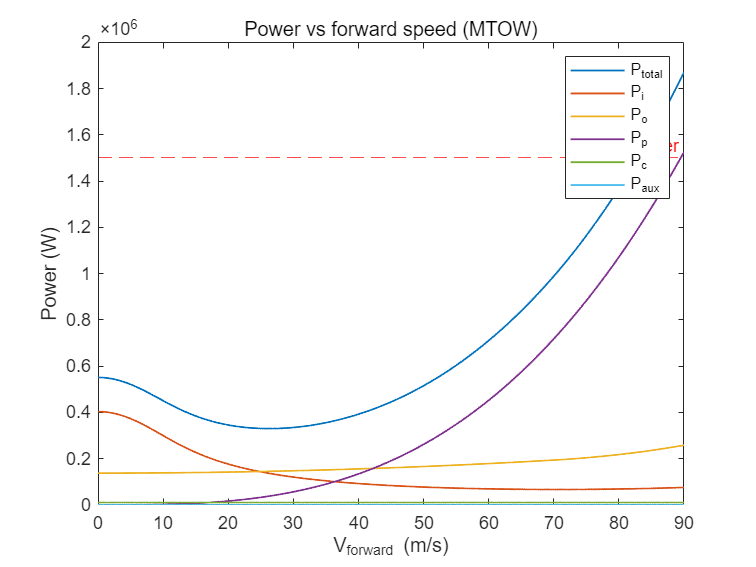

figure
plot(V_forward,P_msl_ceiling_M,LineWidth=1)
hold on
plot(V_forward,Pi_msl_M,LineWidth=1)
hold on
plot(V_forward,Po_msl,LineWidth=1)
hold on
plot(V_forward,Pp_msl,LineWidth=1)
hold on
plot(V_forward,Pc_msl_M,LineWidth=1)
hold on
plot(V_forward,Paux_msl,LineWidth=1)
hold on
yline(Ptotal, '--r', 'Total Power');  % 红色虚线，并加标签
hold on
legend('P_t_o_t_a_l','P_i','P_o','P_p','P_c','P_a_u_x')
title('Power vs forward speed (MTOW)')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('Power (W)')
hold off

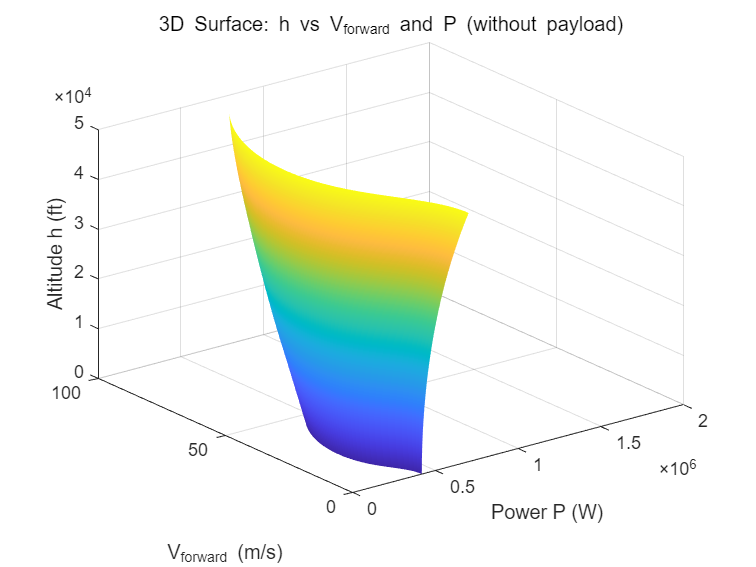

%%%%%% Ceiling for GTOW&MTOW
h = 0:10:50000;
P_ceiling_G = zeros(length(h),length(V_forward));
P_ceiling_M = zeros(length(h),length(V_forward));
mu = V_forward ./ (omega * R);
for j = 1:length(V_forward)
    muu = mu(j);
    for ii = 1:length(h)
        h1 = h(ii);
        % Pi clac
        CT_G = GTOW/(2*rho_0*(1-6.876*10^-6*h1)^4.265*A*omega^2*R^2);
        lambda_initial_G = sqrt(CT_G/2);
        lambda_n = lambda_initial_G;
        lambda_n1 = 0;
        for i = 1:100
            lambda_n1 = muu*tan(alp(j)) + CT_G / (2*sqrt(muu^2 + lambda_n^2));
            lambda_n = lambda_n1;
        end
        lambda_G = lambda_n1;
        CT_M = MTOW/(2*rho_0*(1-6.876*10^-6*h1)^4.265*A*omega^2*R^2);
        lambda_initial_M = sqrt(CT_M/2);
        lambda_n = lambda_initial_M;
        lambda_n1 = 0;
        for i = 1:100
            lambda_n1 = muu*tan(alp(j)) + CT_M / (2*sqrt(muu^2 + lambda_n^2));
            lambda_n = lambda_n1;
        end
        lambda_M = lambda_n1;
        kappa_i = kappa_ii * cosh(7.5 * muu^2);
        Pi_G = (kappa_int * GTOW/2 * omega * R * 2) * lambda_G * kappa_i;
        Pi_M = (kappa_int * MTOW/2 * omega * R * 2) * lambda_M * kappa_i;
        Cpp_ceil = (0.5 * f / A) * muu^3;
        Pp_ceil = Cpp_ceil * (rho_0*(1-6.876*10^-6*h1)^4.265 * A * omega^3 * R^3);
        Pc_ceil_G = 0.3 * GTOW;
        Pc_ceil_M = 0.3 * MTOW;
        Paux_ceil = Paux_msl(j);
        Cpo_pure = sigema * Cd0 * (1 + kappa_02*muu^2 + kappa_04*muu^4) / 8;
        h_M = h1;
        M_19 = (omega * R + V_forward(j)) / sqrt(gamma * R_0 * ((15 - 0.001981 * h_M) + T_trans));
        M_hat = (M_19^2 - 1) / (1.79 * M_19^(4/3) * t_c^(2/3));
        M_hover = (omega * R) / sqrt(gamma * R_0 * ((15 - 0.001981 * h_M) + T_trans));
        if M_19 >= M_dd
            delta_Cpo1 = sigema * (0.3 * (1+muu)^(5/2) * t_c^(5/2) * (M_hat+1)^2);
        else
            delta_Cpo1 = 0;
        end
        % Assumption: tip relief only occurs at RC6-08 part (85%---100%)
        M_r = M_hover*(1+muu)*cos(sweep);
        if M_r >= M_dd
            psi1 = asin(muu^-1 * (M_dd/M_hover - 1));
            psi2 = 180 - psi1;
            f = @(psi,r) (r + muu*sin(psi))^3 * r * (0.165*M_hover*(r+muu*sin(psi))*cos(sweep)-0.0895)
            delta_Cpo2 = sigema * integral2(f,psi1,psi2,@(psi) M_dd/M_hover - muu*sin(psi),1) / (4 * pi)
        else
            delta_Cpo2 = 0;
        end
        delta_Cpo = delta_Cpo2 + delta_Cpo1;
        Po_ceil = (Cpo_pure+delta_Cpo) * 2 * A * omega^3 * R^3 * rho_0*(1-6.876*10^-6*h1)^4.265;
        P_ceiling_G(ii,j) = kappa_trans * (Pi_G + Po_ceil + Pp_ceil + Pc_ceil_G + Paux_ceil);
        P_ceiling_M(ii,j) = kappa_trans * (Pi_M + Po_ceil + Pp_ceil + Pc_ceil_M + Paux_ceil);
    end
end
[VV, HH] = meshgrid(V_forward, h);
figure
surf(P_ceiling_G, VV, HH);
xlabel('Power P (W)');
ylabel('V_f_o_r_w_a_r_d (m/s)');
zlabel('Altitude h (ft)');
title('3D Surface: h vs V_f_o_r_w_a_r_d and P (without payload)');
grid on
shading interp
hold off

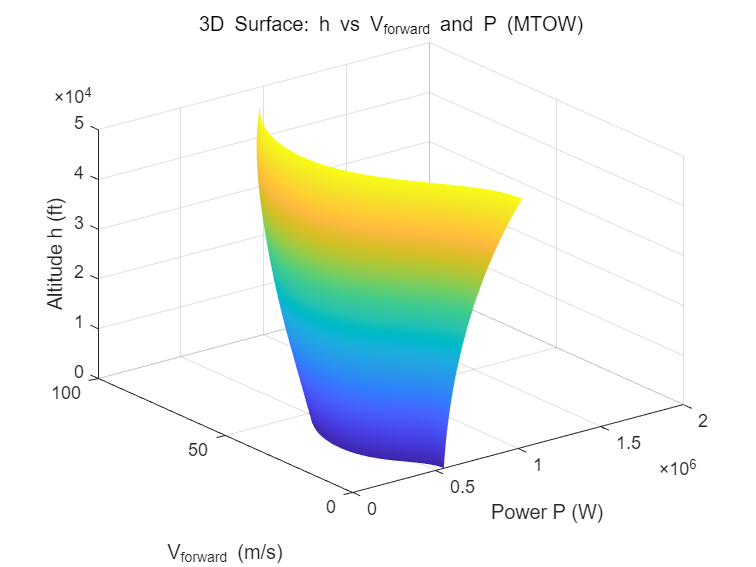

figure
surf(P_ceiling_M, VV, HH);
xlabel('Power P (W)');
ylabel('V_f_o_r_w_a_r_d (m/s)');
zlabel('Altitude h (ft)');
title('3D Surface: h vs V_f_o_r_w_a_r_d and P (MTOW)');
grid on
shading interp
hold off

%%%%%% Max range&endurance

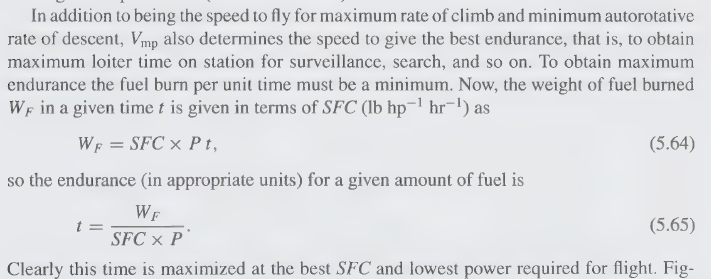

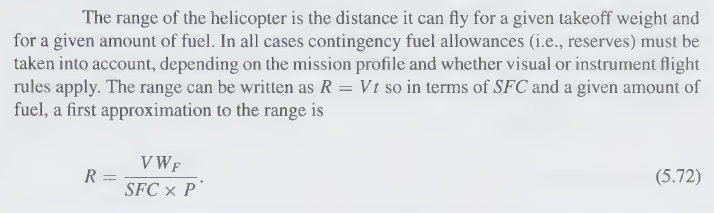

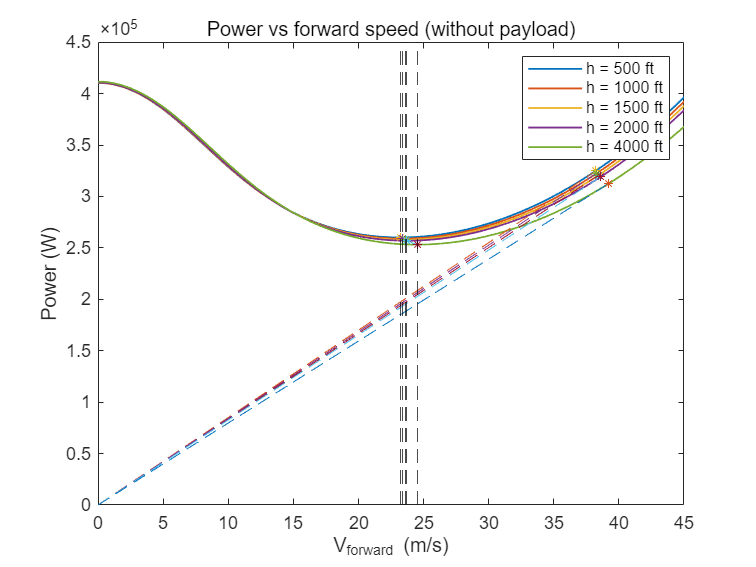

% h in feets
input = zeros(1,18);
input(1) = omega;
input(2) = R;
input(3) = A;
input(4) = rho_0;
input(5) = kappa_ii;
input(6) = kappa_int;
input(7) = f;
input(8) = Paux_total;
input(9) = sigema;
input(10) = Cd0;
input(11) = kappa_02;
input(12) = kappa_04;
input(13) = gamma;
input(14) = R_0;
input(15) = t_c;
input(16) = sweep;
input(17) = M_dd;
input(18) = kappa_trans;

h_cruise = 1500;
h_1 = 500;
h_2 = 1000;
h_3 = 2000;
h_4 = 4000;
T_cruise = (15-0.001981*h_cruise) + T_trans;
T_1 = (15-0.001981*h_1) + T_trans;
T_2 = (15-0.001981*h_2) + T_trans;
T_3 = (15-0.001981*h_3) + T_trans;
T_4 = (15-0.001981*h_4) + T_trans;
P_cruise_G = PowerClac(GTOW,h_cruise,T_cruise,alp ,V_forward,input);
P_1_G = PowerClac(GTOW,h_1,T_1,alp ,V_forward,input);
P_2_G = PowerClac(GTOW,h_2,T_2,alp ,V_forward,input);
P_3_G = PowerClac(GTOW,h_3,T_3,alp ,V_forward,input);
P_4_G = PowerClac(GTOW,h_4,T_4,alp ,V_forward,input);
[Pmp_cruise, idx_cruise] = min(P_cruise_G);
[Pmp_1, idx_1] = min(P_1_G);
[Pmp_2, idx_2] = min(P_2_G);
[Pmp_3, idx_3] = min(P_3_G);
[Pmp_4, idx_4] = min(P_4_G);
hmp_G = [h_1,h_2,h_cruise,h_3,h_4];
Vmp_G = [V_forward(idx_1),V_forward(idx_2),V_forward(idx_cruise),V_forward(idx_3),V_forward(idx_4)];
Pmp_G = [Pmp_1,Pmp_2,Pmp_cruise,Pmp_3,Pmp_4];
endurance_G = (Wf./g) ./ (SFC .* Pmp_G);
k_cruise = P_cruise_G ./ V_forward;
k_1 = P_1_G ./ V_forward;
k_2 = P_2_G ./ V_forward;
k_3 = P_3_G ./ V_forward;
k_4 = P_4_G ./ V_forward;
[~, idx_range_cruise] = min(k_cruise);
[~, idx_range_1] = min(k_1);
[~, idx_range_2] = min(k_2);
[~, idx_range_3] = min(k_3);
[~, idx_range_4] = min(k_4);
hrange_G = [h_1,h_2,h_cruise,h_3,h_4];
Vrange_G = [V_forward(idx_range_1),V_forward(idx_range_2),V_forward(idx_range_cruise),V_forward(idx_range_3),V_forward(idx_range_4)];
Prange_G = [P_1_G(idx_range_1),P_2_G(idx_range_2),P_cruise_G(idx_range_cruise),P_3_G(idx_range_3),P_4_G(idx_range_4)];
range_G = (Vrange_G .* (Wf./g)) ./ (SFC .* Prange_G);
figure
plot(V_forward,P_1_G,LineWidth=1)
hold on
plot(V_forward,P_2_G,LineWidth=1)
hold on
plot(V_forward,P_cruise_G,LineWidth=1)
hold on
plot(V_forward,P_3_G,LineWidth=1)
hold on
plot(V_forward,P_4_G,LineWidth=1)
hold on
plot(Vmp_G,Pmp_G)
hold on
plot([0,V_forward(idx_range_cruise)], [0,P_cruise_G(idx_range_cruise)],'--');
hold on
plot(V_forward(idx_range_cruise), P_cruise_G(idx_range_cruise), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot([0,V_forward(idx_range_1)], [0,P_1_G(idx_range_1)],'--');
hold on
plot(V_forward(idx_range_1), P_1_G(idx_range_1), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot([0,V_forward(idx_range_2)], [0,P_2_G(idx_range_2)],'--');
hold on
plot(V_forward(idx_range_2), P_2_G(idx_range_2), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot([0,V_forward(idx_range_3)], [0,P_3_G(idx_range_3)],'--');
hold on
plot(V_forward(idx_range_3), P_3_G(idx_range_3), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot([0,V_forward(idx_range_4)], [0,P_4_G(idx_range_4)],'--');
hold on
plot(V_forward(idx_range_4), P_4_G(idx_range_4), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
xline(Vmp_G(1),'--k')
hold on
plot(Vmp_G(1), Pmp_G(1), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
xline(Vmp_G(2),'--k')
hold on
plot(Vmp_G(2), Pmp_G(2), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
xline(Vmp_G(3),'--k')
hold on
plot(Vmp_G(3), Pmp_G(3), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
xline(Vmp_G(4),'--k')
hold on
plot(Vmp_G(4), Pmp_G(4), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
xline(Vmp_G(5),'--k')
hold on
plot(Vmp_G(5), Pmp_G(5), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
legend(['h = ',num2str(h_1),' ft'],['h = ',num2str(h_2),' ft'],['h = ',num2str(h_cruise),' ft'],['h = ',num2str(h_3),' ft'],['h = ',num2str(h_4),' ft'])
title('Power vs forward speed (without payload)')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('Power (W)')
xlim([0 45])
hold off

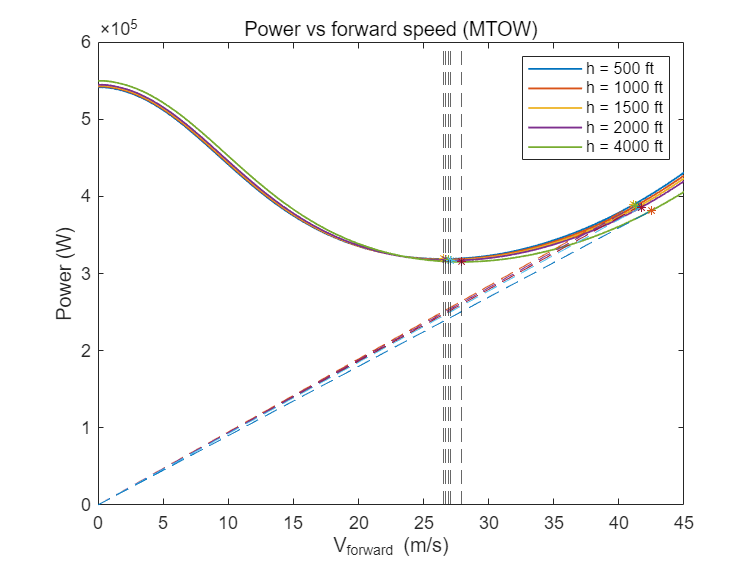

P_cruise_M = PowerClac(MTOW,h_cruise,T_cruise,alp ,V_forward,input);
P_1_M = PowerClac(MTOW,h_1,T_1,alp ,V_forward,input);
P_2_M = PowerClac(MTOW,h_2,T_2,alp ,V_forward,input);
P_3_M = PowerClac(MTOW,h_3,T_3,alp ,V_forward,input);
P_4_M = PowerClac(MTOW,h_4,T_4,alp ,V_forward,input);
[Pmp_cruise, idx_cruise] = min(P_cruise_M);
[Pmp_1, idx_1] = min(P_1_M);
[Pmp_2, idx_2] = min(P_2_M);
[Pmp_3, idx_3] = min(P_3_M);
[Pmp_4, idx_4] = min(P_4_M);
hmp_M = [h_1,h_2,h_cruise,h_3,h_4];
Vmp_M = [V_forward(idx_1),V_forward(idx_2),V_forward(idx_cruise),V_forward(idx_3),V_forward(idx_4)];
Pmp_M = [Pmp_1,Pmp_2,Pmp_cruise,Pmp_3,Pmp_4];
endurance_M = (Wf./g) ./ (SFC .* Pmp_M);
k_cruise = P_cruise_M ./ V_forward;
k_1 = P_1_M ./ V_forward;
k_2 = P_2_M ./ V_forward;
k_3 = P_3_M ./ V_forward;
k_4 = P_4_M ./ V_forward;
[~, idx_range_cruise] = min(k_cruise);
[~, idx_range_1] = min(k_1);
[~, idx_range_2] = min(k_2);
[~, idx_range_3] = min(k_3);
[~, idx_range_4] = min(k_4);
hrange = [h_1,h_2,h_cruise,h_3,h_4];
Vrange_M = [V_forward(idx_range_1),V_forward(idx_range_2),V_forward(idx_range_cruise),V_forward(idx_range_3),V_forward(idx_range_4)];
Prange_M = [P_1_M(idx_range_1),P_2_M(idx_range_2),P_cruise_M(idx_range_cruise),P_3_M(idx_range_3),P_4_M(idx_range_4)];
range_M = (Vrange_M .* (Wf./g)) ./ (SFC .* Prange_M);
figure
plot(V_forward,P_1_M,LineWidth=1)
hold on
plot(V_forward,P_2_M,LineWidth=1)
hold on
plot(V_forward,P_cruise_M,LineWidth=1)
hold on
plot(V_forward,P_3_M,LineWidth=1)
hold on
plot(V_forward,P_4_M,LineWidth=1)
hold on
plot(Vmp_M,Pmp_M)
hold on
plot([0,V_forward(idx_range_cruise)], [0,P_cruise_M(idx_range_cruise)],'--');
hold on
plot(V_forward(idx_range_cruise), P_cruise_M(idx_range_cruise), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot([0,V_forward(idx_range_1)], [0,P_1_M(idx_range_1)],'--');
hold on
plot(V_forward(idx_range_1), P_1_M(idx_range_1), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot([0,V_forward(idx_range_2)], [0,P_2_M(idx_range_2)],'--');
hold on
plot(V_forward(idx_range_2), P_2_M(idx_range_2), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot([0,V_forward(idx_range_3)], [0,P_3_M(idx_range_3)],'--');
hold on
plot(V_forward(idx_range_3), P_3_M(idx_range_3), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot([0,V_forward(idx_range_4)], [0,P_4_M(idx_range_4)],'--');
hold on
plot(V_forward(idx_range_4), P_4_M(idx_range_4), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
xline(Vmp_M(1),'--')
hold on
plot(Vmp_M(1), Pmp_M(1), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
xline(Vmp_M(2),'--')
hold on
plot(Vmp_M(2), Pmp_M(2), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
xline(Vmp_M(3),'--')
hold on
plot(Vmp_M(3), Pmp_M(3), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
xline(Vmp_M(4),'--')
hold on
plot(Vmp_M(4), Pmp_M(4), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
xline(Vmp_M(5),'--')
hold on
plot(Vmp_M(5), Pmp_M(5), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
legend(['h = ',num2str(h_1),' ft'],['h = ',num2str(h_2),' ft'],['h = ',num2str(h_cruise),' ft'],['h = ',num2str(h_3),' ft'],['h = ',num2str(h_4),' ft'])
title('Power vs forward speed (MTOW)')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('Power (W)')
xlim([0 45])
hold off

Trange = table(hrange',Vrange_M',Prange_M',range_M',Vrange_G',Prange_G',range_G');
Tendurance = table(hmp_G',Vmp_M',Pmp_M',endurance_M',Vmp_G',Pmp_G',endurance_G');
%% height V_MTOW  P_MTOW     quality     V_GTOW  P_GTOW     quality   
disp(Trange)

    Var1    Var2       Var3          Var4       Var5       Var6          Var7   
    ____    ____    __________    __________    ____    __________    __________

     500    41.1    3.8916e+05    6.2603e+05    38.2    3.2482e+05    6.9711e+05
    1000    41.3    3.8803e+05    6.3091e+05    38.3    3.2262e+05    7.0371e+05
    1500    41.5    3.8692e+05    6.3578e+05    38.4    3.2045e+05    7.1032e+05
    2000    41.7    3.8583e+05    6.4065e+05    38.6    3.1913e+05    7.1696e+05
    4000    42.5    3.8171e+05    6.5999e+05    39.2    3.1245e+05    7.4368e+05



disp(Tendurance)

    Var1    Var2       Var3       Var4     Var5       Var6       Var7 
    ____    ____    __________    _____    ____    __________    _____

     500    26.5    3.1901e+05    18581    23.2    2.6017e+05    22784
    1000    26.7    3.1836e+05    18620    23.4    2.5908e+05    22880
    1500    26.9    3.1774e+05    18656    23.6    2.5802e+05    22974
    2000    27.1    3.1716e+05    18690    23.7    2.5699e+05    23066
    4000    27.9    3.1521e+05    18805    24.5     2.532e+05    23411



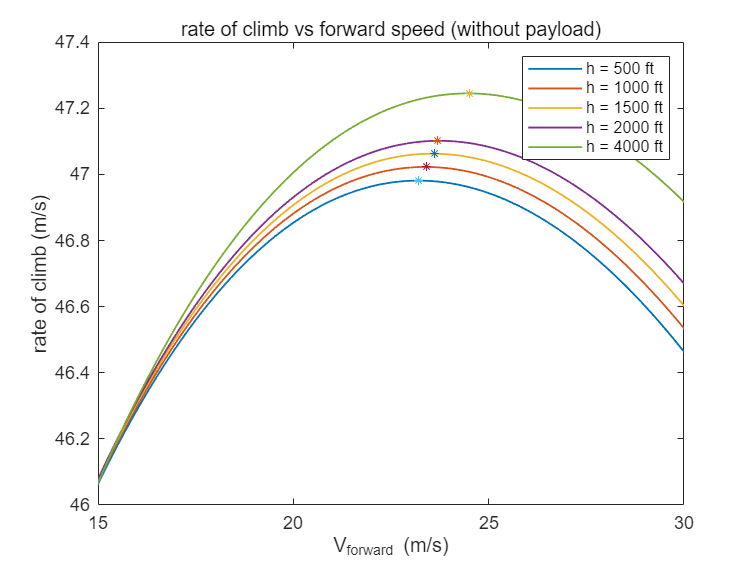

%%%%%% Climb performance (V_forward indicates climb speed, Vc indicates rate of climb )
Vc_1_M = (Ptotal - P_1_M) ./ MTOW;
Vc_2_M = (Ptotal - P_2_M) / MTOW;
Vc_cruise_M = (Ptotal - P_cruise_M) / MTOW;
Vc_3_M = (Ptotal - P_3_M) / MTOW;
Vc_4_M = (Ptotal - P_4_M) / MTOW;
Vc_1_G = (Ptotal - P_1_G) / GTOW;
Vc_2_G = (Ptotal - P_2_G) / GTOW;
Vc_cruise_G = (Ptotal - P_cruise_G) / GTOW;
Vc_3_G = (Ptotal - P_3_G) / GTOW;
Vc_4_G = (Ptotal - P_4_G) / GTOW;
Vc_1_G(Vc_1_G < 0) = 0;
Vc_2_G(Vc_2_G < 0) = 0;
Vc_cruise_G(Vc_cruise_G < 0) = 0;
Vc_3_G(Vc_3_G < 0) = 0;
Vc_4_G(Vc_4_G < 0) = 0;
Vc_1_M(Vc_1_M < 0) = 0;
Vc_2_M(Vc_2_M < 0) = 0;
Vc_cruise_M(Vc_cruise_M < 0) = 0;
Vc_3_M(Vc_3_M < 0) = 0;
Vc_4_M(Vc_4_M < 0) = 0;
[Vc_max_1_G,idx_Vc_1_G] = max(Vc_1_G);
[Vc_max_2_G,idx_Vc_2_G] = max(Vc_2_G);
[Vc_max_cruise_G,idx_Vc_cruise_G] = max(Vc_cruise_G);
[Vc_max_3_G,idx_Vc_3_G] = max(Vc_3_G);
[Vc_max_4_G,idx_Vc_4_G] = max(Vc_4_G);
[Vc_max_1_M,idx_Vc_1_M] = max(Vc_1_M);
[Vc_max_2_M,idx_Vc_2_M] = max(Vc_2_M);
[Vc_max_cruise_M,idx_Vc_cruise_M] = max(Vc_cruise_M);
[Vc_max_3_M,idx_Vc_3_M] = max(Vc_3_M);
[Vc_max_4_M,idx_Vc_4_M] = max(Vc_4_M);
figure
plot(V_forward,Vc_1_G,LineWidth=1);
hold on
plot(V_forward,Vc_2_G,LineWidth=1);
hold on
plot(V_forward,Vc_cruise_G,LineWidth=1);
hold on
plot(V_forward,Vc_3_G,LineWidth=1);
hold on
plot(V_forward,Vc_4_G,LineWidth=1);
hold on
plot(V_forward(idx_Vc_1_G), Vc_1_G(idx_Vc_1_G), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_2_G), Vc_2_G(idx_Vc_2_G), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_cruise_G), Vc_cruise_G(idx_Vc_cruise_G), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_3_G), Vc_3_G(idx_Vc_3_G), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_4_G), Vc_4_G(idx_Vc_4_G), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
legend(['h = ',num2str(h_1),' ft'],['h = ',num2str(h_2),' ft'],['h = ',num2str(h_cruise),' ft'],['h = ',num2str(h_3),' ft'],['h = ',num2str(h_4),' ft'])
title('rate of climb vs forward speed (without payload)')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('rate of climb (m/s)')
xlim([15 30])
hold off

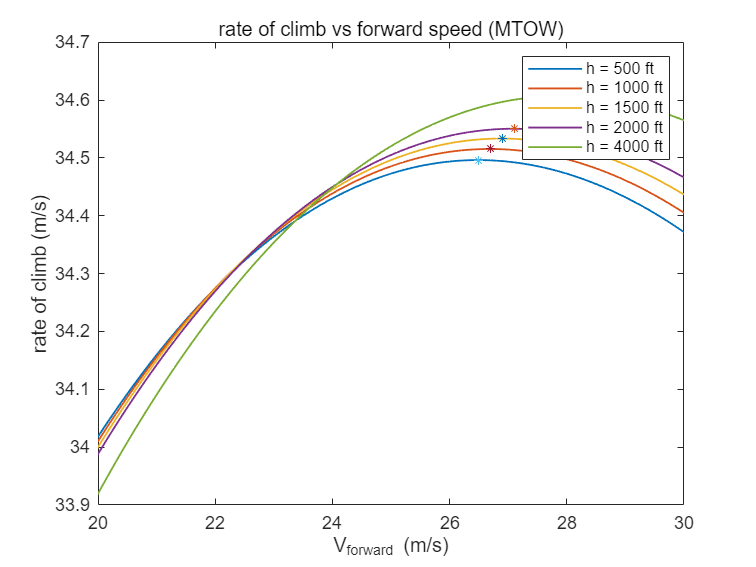

figure
plot(V_forward,Vc_1_M,LineWidth=1);
hold on
plot(V_forward,Vc_2_M,LineWidth=1);
hold on
plot(V_forward,Vc_cruise_M,LineWidth=1);
hold on
plot(V_forward,Vc_3_M,LineWidth=1);
hold on
plot(V_forward,Vc_4_M,LineWidth=1);
hold on
plot(V_forward(idx_Vc_1_M), Vc_1_M(idx_Vc_1_M), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_2_M), Vc_2_M(idx_Vc_2_M), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_cruise_M), Vc_cruise_M(idx_Vc_cruise_M), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_3_M), Vc_3_M(idx_Vc_3_M), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_4_M), Vc_4_M(idx_Vc_4_M), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
legend(['h = ',num2str(h_1),' ft'],['h = ',num2str(h_2),' ft'],['h = ',num2str(h_cruise),' ft'],['h = ',num2str(h_3),' ft'],['h = ',num2str(h_4),' ft'])
title('rate of climb vs forward speed (MTOW)')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('rate of climb (m/s)')
xlim([20 30])
hold off

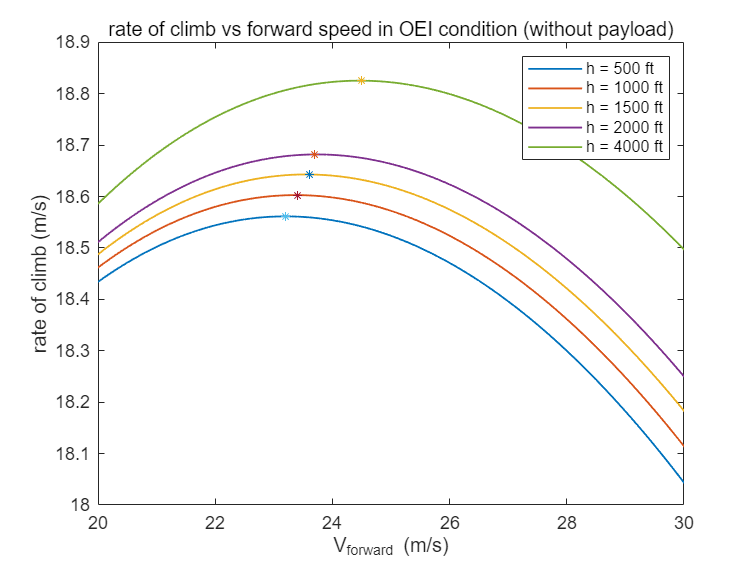

%%%%%% Climb performance OEI
Vc_1_M_OEI = (Ptotal/2 - P_1_M) ./ MTOW;
Vc_2_M_OEI = (Ptotal/2 - P_2_M) / MTOW;
Vc_cruise_M_OEI = (Ptotal/2 - P_cruise_M) / MTOW;
Vc_3_M_OEI = (Ptotal/2 - P_3_M) / MTOW;
Vc_4_M_OEI = (Ptotal/2 - P_4_M) / MTOW;
Vc_1_G_OEI = (Ptotal/2 - P_1_G) / GTOW;
Vc_2_G_OEI = (Ptotal/2 - P_2_G) / GTOW;
Vc_cruise_G_OEI = (Ptotal/2 - P_cruise_G) / GTOW;
Vc_3_G_OEI = (Ptotal/2 - P_3_G) / GTOW;
Vc_4_G_OEI = (Ptotal/2 - P_4_G) / GTOW;
Vc_1_G_OEI(Vc_1_G_OEI < 0) = 0;
Vc_2_G_OEI(Vc_2_G_OEI < 0) = 0;
Vc_cruise_G_OEI(Vc_cruise_G_OEI < 0) = 0;
Vc_3_G_OEI(Vc_3_G_OEI < 0) = 0;
Vc_4_G_OEI(Vc_4_G_OEI < 0) = 0;
Vc_1_M_OEI(Vc_1_M_OEI < 0) = 0;
Vc_2_M_OEI(Vc_2_M_OEI < 0) = 0;
Vc_cruise_M_OEI(Vc_cruise_M_OEI < 0) = 0;
Vc_3_M_OEI(Vc_3_M_OEI < 0) = 0;
Vc_4_M_OEI(Vc_4_M_OEI < 0) = 0;
[Vc_max_1_G_OEI,idx_Vc_1_G_OEI] = max(Vc_1_G_OEI);
[Vc_max_2_G_OEI,idx_Vc_2_G_OEI] = max(Vc_2_G);
[Vc_max_cruise_G_OEI,idx_Vc_cruise_G_OEI] = max(Vc_cruise_G_OEI);
[Vc_max_3_G_OEI,idx_Vc_3_G_OEI] = max(Vc_3_G_OEI);
[Vc_max_4_G_OEI,idx_Vc_4_G_OEI] = max(Vc_4_G_OEI);
[Vc_max_1_M_OEI,idx_Vc_1_M_OEI] = max(Vc_1_M_OEI);
[Vc_max_2_M_OEI,idx_Vc_2_M_OEI] = max(Vc_2_M_OEI);
[Vc_max_cruise_M_OEI,idx_Vc_cruise_M_OEI] = max(Vc_cruise_M_OEI);
[Vc_max_3_M_OEI,idx_Vc_3_M_OEI] = max(Vc_3_M_OEI);
[Vc_max_4_M_OEI,idx_Vc_4_M_OEI] = max(Vc_4_M_OEI);
figure
plot(V_forward,Vc_1_G_OEI,LineWidth=1);
hold on
plot(V_forward,Vc_2_G_OEI,LineWidth=1);
hold on
plot(V_forward,Vc_cruise_G_OEI,LineWidth=1);
hold on
plot(V_forward,Vc_3_G_OEI,LineWidth=1);
hold on
plot(V_forward,Vc_4_G_OEI,LineWidth=1);
hold on
plot(V_forward(idx_Vc_1_G_OEI), Vc_1_G_OEI(idx_Vc_1_G_OEI), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_2_G_OEI), Vc_2_G_OEI(idx_Vc_2_G_OEI), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_cruise_G_OEI), Vc_cruise_G_OEI(idx_Vc_cruise_G_OEI), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_3_G_OEI), Vc_3_G_OEI(idx_Vc_3_G_OEI), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_4_G_OEI), Vc_4_G_OEI(idx_Vc_4_G_OEI), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
legend(['h = ',num2str(h_1),' ft'],['h = ',num2str(h_2),' ft'],['h = ',num2str(h_cruise),' ft'],['h = ',num2str(h_3),' ft'],['h = ',num2str(h_4),' ft'])
title('rate of climb vs forward speed in OEI condition (without payload)')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('rate of climb (m/s)')
xlim([20 30])
hold off

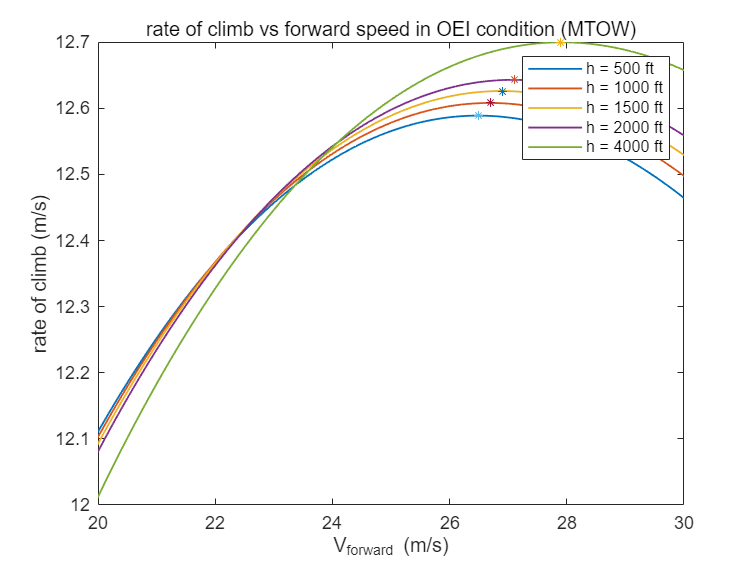

figure
plot(V_forward,Vc_1_M_OEI,LineWidth=1);
hold on
plot(V_forward,Vc_2_M_OEI,LineWidth=1);
hold on
plot(V_forward,Vc_cruise_M_OEI,LineWidth=1);
hold on
plot(V_forward,Vc_3_M_OEI,LineWidth=1);
hold on
plot(V_forward,Vc_4_M_OEI,LineWidth=1);
hold on
plot(V_forward(idx_Vc_1_M_OEI), Vc_1_M_OEI(idx_Vc_1_M_OEI), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_2_M_OEI), Vc_2_M_OEI(idx_Vc_2_M_OEI), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_cruise_M_OEI), Vc_cruise_M_OEI(idx_Vc_cruise_M_OEI), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_3_M_OEI), Vc_3_M_OEI(idx_Vc_3_M_OEI), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
hold on
plot(V_forward(idx_Vc_4_M_OEI), Vc_4_M_OEI(idx_Vc_4_M_OEI), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'y');
legend(['h = ',num2str(h_1),' ft'],['h = ',num2str(h_2),' ft'],['h = ',num2str(h_cruise),' ft'],['h = ',num2str(h_3),' ft'],['h = ',num2str(h_4),' ft'])
title('rate of climb vs forward speed in OEI condition (MTOW)')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('rate of climb (m/s)')
xlim([20 30])
hold off

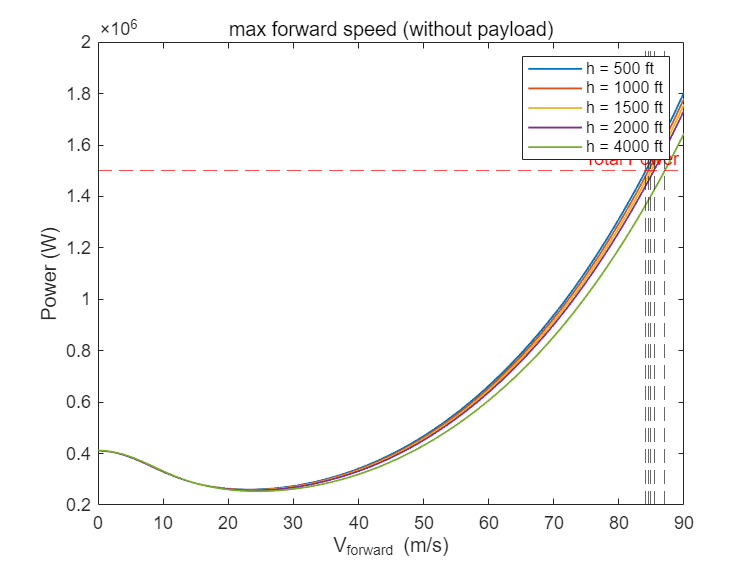

%%%%%% max forward speed
[~,idx_Vmax_1_G] = min(abs(P_1_G - Ptotal));
[~,idx_Vmax_2_G] = min(abs(P_2_G - Ptotal));
[~,idx_Vmax_cruise_G] = min(abs(P_cruise_G - Ptotal));
[~,idx_Vmax_3_G] = min(abs(P_3_G - Ptotal));
[~,idx_Vmax_4_G] = min(abs(P_4_G - Ptotal));
[~,idx_Vmax_1_M] = min(abs(P_1_M - Ptotal));
[~,idx_Vmax_2_M] = min(abs(P_2_M - Ptotal));
[~,idx_Vmax_cruise_M] = min(abs(P_cruise_M - Ptotal));
[~,idx_Vmax_3_M] = min(abs(P_3_M - Ptotal));
[~,idx_Vmax_4_M] = min(abs(P_4_M - Ptotal));
figure
plot(V_forward,P_1_G,LineWidth=1)
hold on
plot(V_forward,P_2_G,LineWidth=1)
hold on
plot(V_forward,P_cruise_G,LineWidth=1)
hold on
plot(V_forward,P_3_G,LineWidth=1)
hold on
plot(V_forward,P_4_G,LineWidth=1)
hold on
yline(Ptotal, '--r', 'Total Power');
hold on
xline(V_forward(idx_Vmax_1_G),'--')
hold on
xline(V_forward(idx_Vmax_2_G),'--')
hold on
xline(V_forward(idx_Vmax_3_G),'--')
hold on
xline(V_forward(idx_Vmax_4_G),'--')
hold on
xline(V_forward(idx_Vmax_cruise_G),'--')
legend(['h = ',num2str(h_1),' ft'],['h = ',num2str(h_2),' ft'],['h = ',num2str(h_cruise),' ft'],['h = ',num2str(h_3),' ft'],['h = ',num2str(h_4),' ft'])
title('max forward speed (without payload)')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('Power (W)')
hold off

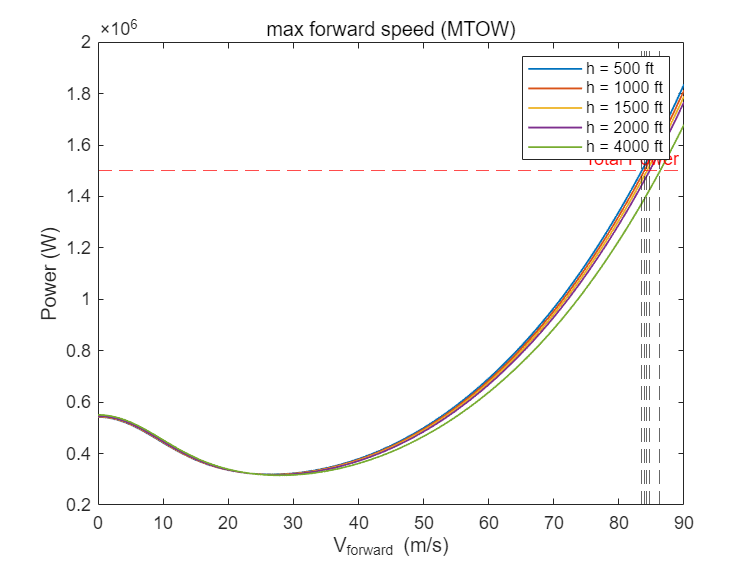

figure
plot(V_forward,P_1_M,LineWidth=1)
hold on
plot(V_forward,P_2_M,LineWidth=1)
hold on
plot(V_forward,P_cruise_M,LineWidth=1)
hold on
plot(V_forward,P_3_M,LineWidth=1)
hold on
plot(V_forward,P_4_M,LineWidth=1)
hold on
yline(Ptotal, '--r', 'Total Power');
hold on
xline(V_forward(idx_Vmax_1_M),'--')
hold on
xline(V_forward(idx_Vmax_2_M),'--')
hold on
xline(V_forward(idx_Vmax_3_M),'--')
hold on
xline(V_forward(idx_Vmax_4_M),'--')
hold on
xline(V_forward(idx_Vmax_cruise_M),'--')
legend(['h = ',num2str(h_1),' ft'],['h = ',num2str(h_2),' ft'],['h = ',num2str(h_cruise),' ft'],['h = ',num2str(h_3),' ft'],['h = ',num2str(h_4),' ft'])
title('max forward speed (MTOW)')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('Power (W)')
hold off

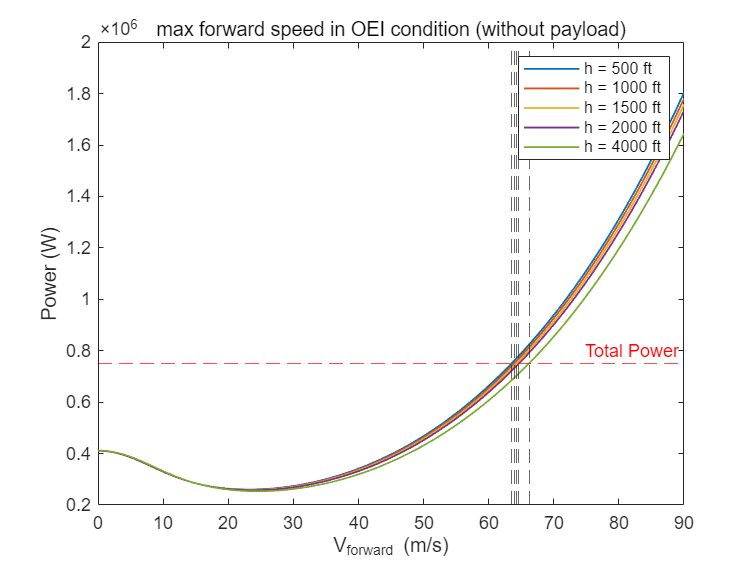

%%%%%% max forward speed (OEI)
Ptotal_OEI = Ptotal/2;
[~,idx_Vmax_1_G] = min(abs(P_1_G - Ptotal_OEI));
[~,idx_Vmax_2_G] = min(abs(P_2_G - Ptotal_OEI));
[~,idx_Vmax_cruise_G] = min(abs(P_cruise_G - Ptotal_OEI));
[~,idx_Vmax_3_G] = min(abs(P_3_G - Ptotal_OEI));
[~,idx_Vmax_4_G] = min(abs(P_4_G - Ptotal_OEI));
[~,idx_Vmax_1_M] = min(abs(P_1_M - Ptotal_OEI));
[~,idx_Vmax_2_M] = min(abs(P_2_M - Ptotal_OEI));
[~,idx_Vmax_cruise_M] = min(abs(P_cruise_M - Ptotal_OEI));
[~,idx_Vmax_3_M] = min(abs(P_3_M - Ptotal_OEI));
[~,idx_Vmax_4_M] = min(abs(P_4_M - Ptotal_OEI));
figure
plot(V_forward,P_1_G,LineWidth=1)
hold on
plot(V_forward,P_2_G,LineWidth=1)
hold on
plot(V_forward,P_cruise_G,LineWidth=1)
hold on
plot(V_forward,P_3_G,LineWidth=1)
hold on
plot(V_forward,P_4_G,LineWidth=1)
hold on
yline(Ptotal_OEI, '--r', 'Total Power');
hold on
xline(V_forward(idx_Vmax_1_G),'--')
hold on
xline(V_forward(idx_Vmax_2_G),'--')
hold on
xline(V_forward(idx_Vmax_3_G),'--')
hold on
xline(V_forward(idx_Vmax_4_G),'--')
hold on
xline(V_forward(idx_Vmax_cruise_G),'--')
legend(['h = ',num2str(h_1),' ft'],['h = ',num2str(h_2),' ft'],['h = ',num2str(h_cruise),' ft'],['h = ',num2str(h_3),' ft'],['h = ',num2str(h_4),' ft'])
title('max forward speed in OEI condition (without payload)')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('Power (W)')
hold off

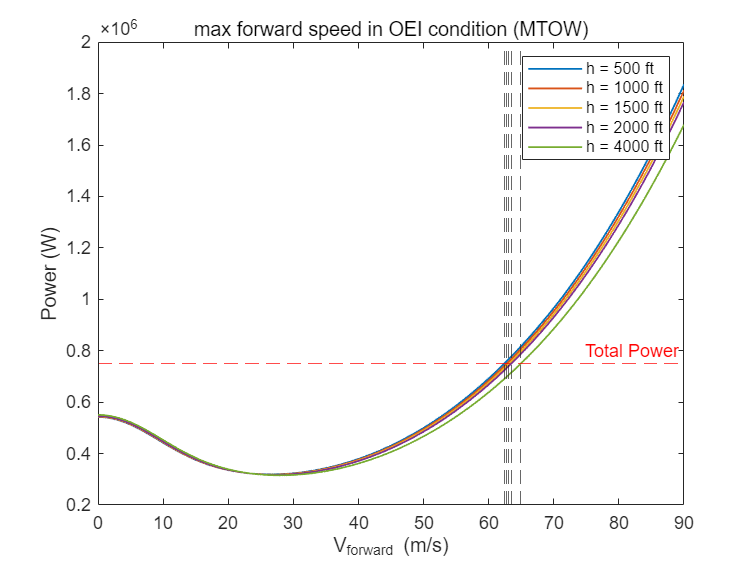

figure
plot(V_forward,P_1_M,LineWidth=1)
hold on
plot(V_forward,P_2_M,LineWidth=1)
hold on
plot(V_forward,P_cruise_M,LineWidth=1)
hold on
plot(V_forward,P_3_M,LineWidth=1)
hold on
plot(V_forward,P_4_M,LineWidth=1)
hold on
xline(V_forward(idx_Vmax_1_M),'--')
hold on
xline(V_forward(idx_Vmax_2_M),'--')
hold on
yline(Ptotal_OEI, '--r', 'Total Power');
hold on
xline(V_forward(idx_Vmax_3_M),'--')
hold on
xline(V_forward(idx_Vmax_4_M),'--')
hold on
xline(V_forward(idx_Vmax_cruise_M),'--')
legend(['h = ',num2str(h_1),' ft'],['h = ',num2str(h_2),' ft'],['h = ',num2str(h_cruise),' ft'],['h = ',num2str(h_3),' ft'],['h = ',num2str(h_4),' ft'])
title('max forward speed in OEI condition (MTOW)')
xlabel('V_f_o_r_w_a_r_d (m/s)')
ylabel('Power (W)')
hold off

%%%%%% Range—Payload and Endurance—Payload Relations

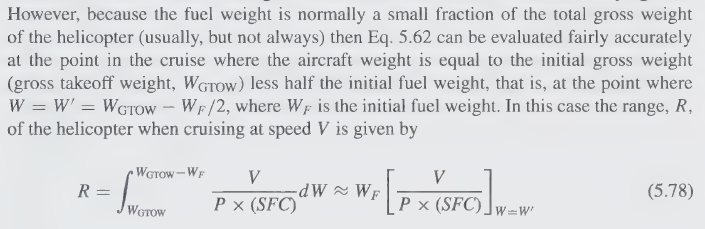

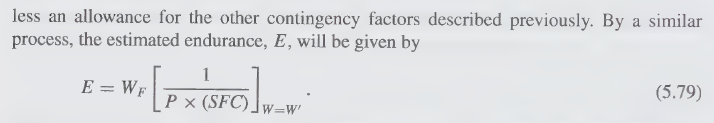

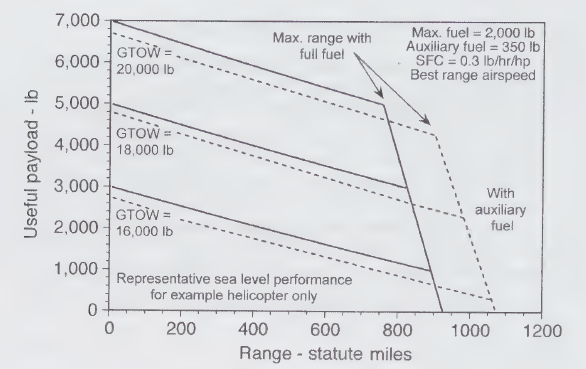

GTOW_diff = 1000; % N
Wf_range = 0:1:Wf;
W_1 = MTOW;
W_2 = W_1 - GTOW_diff;
W_3 = W_2 - GTOW_diff;
W_4 = W_3 - GTOW_diff;
W_5 = W_4 - GTOW_diff;
Wpay_1 = Wpay - Wf_range;
Wpay_2 = Wpay_1 - GTOW_diff;
Wpay_3 = Wpay_2 - GTOW_diff;
Wpay_4 = Wpay_3 - GTOW_diff;
Wpay_5 = Wpay_4 - GTOW_diff;
W = [W_1,W_2,W_3,W_4,W_5];
R_factor = zeros(size(W));
E_factor = zeros(size(W));
for j = 1:length(W)
    h_range = h_cruise;
    mu_range = V_forward ./ (omega * R);
    Pi_range = kappa_int * kappa_i * W(j)^(3/2) / sqrt(4 * rho_0*(1-6.876*10^-6*h_range)^4.265 * A);
    Cpp_range = (0.5 * f / A) .* mu.^3;
    Pp_range = Cpp_range .* (rho_0*(1-6.876*10^-6*h_range)^4.265 * A * omega^3 * R^3);
    Paux_range = Paux_total*ones(size(V_forward));
    % Po calc
    Po_msl = zeros(size(V_forward));
    Cpo_pure = sigema * Cd0 .* (1 + kappa_02.*mu.^2 + kappa_04.*mu.^4) ./ 8;
    h_M = h_range;
    M_19 = (omega * R + V_forward) ./ sqrt(gamma * R_0 * ((15 - 0.001981 * h_M) + T_trans));
    M_hat = (M_19.^2 - 1) ./ (1.79 .* M_19.^(4/3) .* t_c^(2/3));
    M_hover = (omega * R) / sqrt(gamma * R_0 * ((15 - 0.001981 * h_M) + T_trans));
    for i = 1:length(V_forward)
        if M_19(i) >= M_dd
            delta_Cpo = sigema * (0.3 * (1+mu(i))^(5/2) * t_c^(5/2) * (M_hat(i)+1)^2);
        else
            delta_Cpo = 0;
        end
        % Assumption: tip relief only occurs at RC6-08 part (85%---100%)
        M_r = M_hover*(1+mu(i))*cos(sweep);
        if M_r >= M_dd
            psi1 = asin(mu(i)^-1 * (M_dd/M_hover - 1));
            psi2 = 180 - psi1;
            f = @(psi,r) (r + mu(i)*sin(psi))^3 * r * (0.165*M_hover*(r+mu(i)*sin(psi))*cos(sweep)-0.0895)
            delta_Cpo2 = sigema * integral2(f,psi1,psi2,@(psi) M_dd/M_hover - mu(i)*sin(psi),1) / (4 * pi)
        else
            delta_Cpo2 = 0;
        end
        Po_range = (Cpo_pure+delta_Cpo+delta_Cpo2) .* (2 * A * omega^3 * R^3 * rho_0*(1-6.876*10^-6*h_M)^4.265);
    end
    P_range = (Pi_range + Po_range + Pp_range + Paux_range) .* kappa_trans;
    k_range = P_range ./ V_forward;
    [~, idx_range] = min(k_range);
    Vrange = V_forward(idx_range);
    [~, idx_endurance] = min(P_range);
    E_factor(j) = 1 / (P_range(idx_endurance) * SFC);
    R_factor(j) = Vrange / (P_range(idx_range) * SFC);
end
R1 = Wf_range * R_factor(1) *0.001 ./g;
R2 = Wf_range * R_factor(2) *0.001 ./g;
R3 = Wf_range * R_factor(3) *0.001 ./g;
R4 = Wf_range * R_factor(4) *0.001 ./g;
R5 = Wf_range * R_factor(5) *0.001 ./g;
E1 = Wf_range * E_factor(1) ./(g*3600);
E2 = Wf_range * E_factor(2) ./(g*3600);
E3 = Wf_range * E_factor(3) ./(g*3600);
E4 = Wf_range * E_factor(4) ./(g*3600);
E5 = Wf_range * E_factor(5) ./(g*3600);
maxrange = [max(R1),max(R2),max(R3),max(R4),max(R5)];
maxendurance = [max(E1),max(E2),max(E3),max(E4),max(E5)];
minpay = [min(Wpay_1),min(Wpay_2),min(Wpay_3),min(Wpay_4),min(Wpay_5)];
p1 = polyfit(maxrange, minpay, 1);
maxrange_fit = max(R1):0.1:180;
minpay_fit_R = polyval(p1, maxrange_fit);
p2 = polyfit(maxendurance, minpay, 1);
maxendurance_fit = max(E1):0.01:1.4;
minpay_fit_E = polyval(p2, maxendurance_fit);
figure
plot(R1,Wpay_1,LineWidth=1)
hold on
plot(R2,Wpay_2,LineWidth=1)
hold on
plot(R3,Wpay_3,LineWidth=1)
hold on
plot(R4,Wpay_4,LineWidth=1)
hold on
plot(R5,Wpay_5,LineWidth=1)
hold on
plot(maxrange_fit, minpay_fit_R, '--', 'LineWidth', 1, 'DisplayName', 'limitation');
legend(['MTOW = ',num2str(W_1),' N'],['MTOW = ',num2str(W_2),' N'],['MTOW = ',num2str(W_3),' N'],['MTOW = ',num2str(W_4),' N'],['MTOW = ',num2str(W_5),' N'],' limitation')

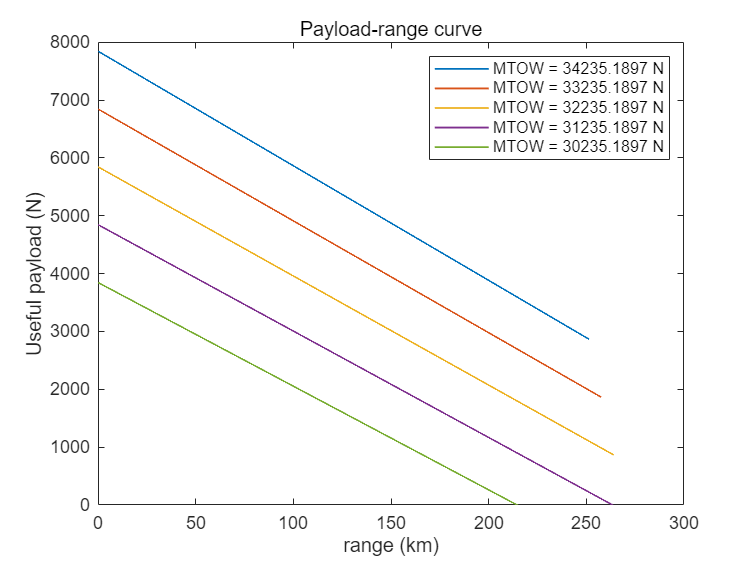

title('Payload-range curve')
xlabel('range (km)')
ylabel('Useful payload (N)')
ylim([0 8000])
hold off

figure
plot(E1,Wpay_1,LineWidth=1)
hold on
plot(E2,Wpay_2,LineWidth=1)
hold on
plot(E3,Wpay_3,LineWidth=1)
hold on
plot(E4,Wpay_4,LineWidth=1)
hold on
plot(E5,Wpay_5,LineWidth=1)
hold on
plot(maxendurance_fit,minpay_fit_E, '--', 'LineWidth', 1, 'DisplayName', 'limitation')
legend(['MTOW = ',num2str(W_1),' N'],['MTOW = ',num2str(W_2),' N'],['MTOW = ',num2str(W_3),' N'],['MTOW = ',num2str(W_4),' N'],['MTOW = ',num2str(W_5),' N'],' limitation')

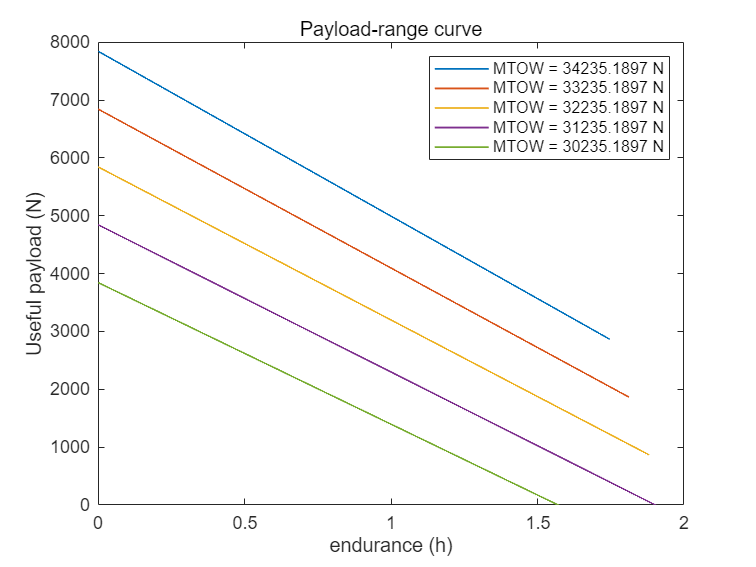

title('Payload-range curve')
xlabel('endurance (h)')
ylabel('Useful payload (N)')
ylim([0 8000])
hold off

%%%%%% fuel consumption (mission profile)






%%%%%% Autorotation (rate of  decent) 

